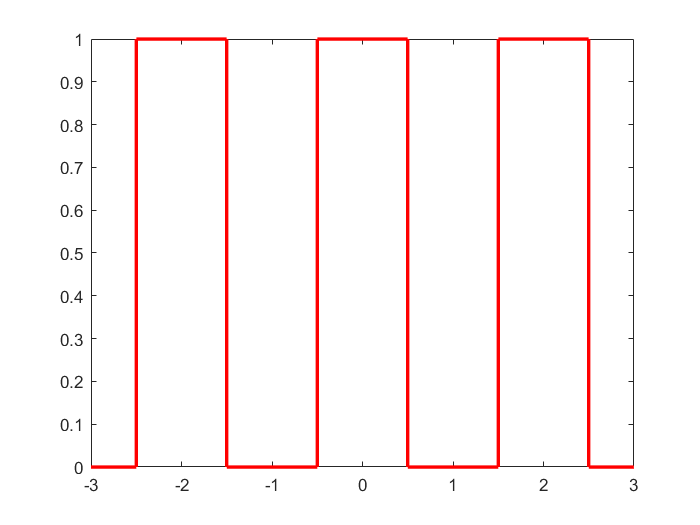

clc
clear
close all

N=3;
T=2;
tvec=-N*T/2:0.001:N*T/2-0.001;
w_0=2*pi/T;
tvec1=-T/2:0.001:T/2-0.001;
x_t=zeros(size(tvec1));
x_t(tvec1> -1/2 & tvec1< 1/2)=1;
sq_wave=[];

for tx=1:N
    sq_wave=[sq_wave x_t];
end

figure(1)
plot(tvec,sq_wave,'r','LineWidth',2);

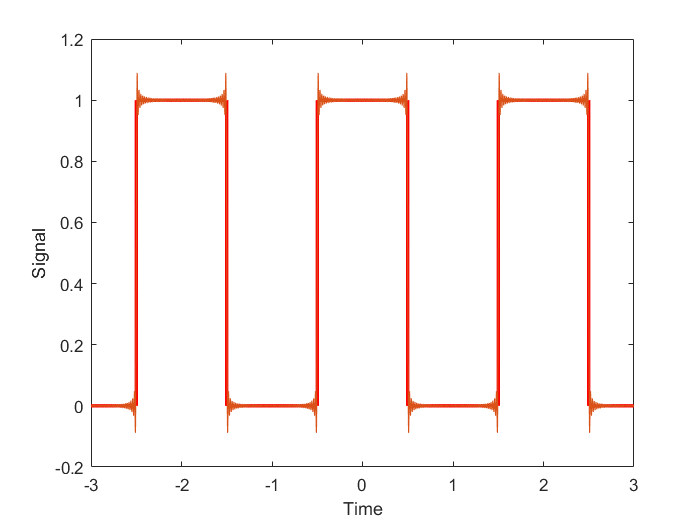


M=100;
for mx=1:M
   %Fourier series
   kvec=-mx:mx;
   for kx=1:length(kvec)
       k=kvec(kx);
       basis1=exp(-1i*k*w_0*tvec1);
       c(kx)=(1/T)*trapz(tvec1,x_t.*basis1);
   end
   %Reconstruction
sq_recon=zeros(size(tvec));
for kx=1:length(kvec)
    k=kvec(kx);
    basis=exp(1i*k*w_0*tvec);
    sq_recon=sq_recon + c(kx)*basis;
end

plot(tvec,sq_wave,'r','Linewidth',2);
hold on;
plot(tvec,sq_recon);
xlabel('Time');
ylabel('Signal');
hold off;
pause(0.5);
drawnow;

recon_err(mx)=mean((abs(sq_recon-sq_wave)).^2);
end

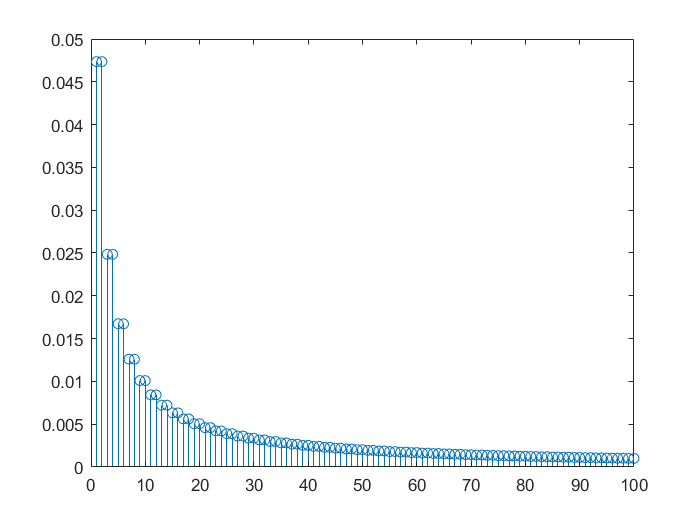


figure;
stem(1:M,(recon_err));